startup_rtb

- Robotics Toolbox for MATLAB (release 10.3)
 - ARTE contributed code: 3D models for robot manipulators (C:\Users\Robert\Documents\MATLAB\Add-Ons\Toolboxes\Robotics Toolbox for MATLAB\code\robot\data\ARTE)
 - pHRIWARE (release 1.1): pHRIWARE is Copyrighted by Bryan Moutrie (2013-2018) (c)


clear; clc;

## Homogeneous transformation in 2D in Matlab

2D translation by 1 unit on x and 2 units on y

transl2(1,2)

ans =      1     0     1
     0     1     2
     0     0     1



% 2D Rotation matrix rotating 30 deg
rot2(30, 'deg')

ans =     0.8660   -0.5000
    0.5000    0.8660



% 2D Rotation matrix rotating 0 rad for homogeneous transformation
trot2(30, 'deg')

ans =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000



% Combining the translation and rotation
transl2(1,2) * trot2(30, 'deg')

ans =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


## Alternative

One can define the same transformation in SE as

SE2(1,2,30,'deg')

 

ans = 
    0.8660   -0.5000         1
    0.5000    0.8660         2
         0         0         1


## Complete example

Set the axis

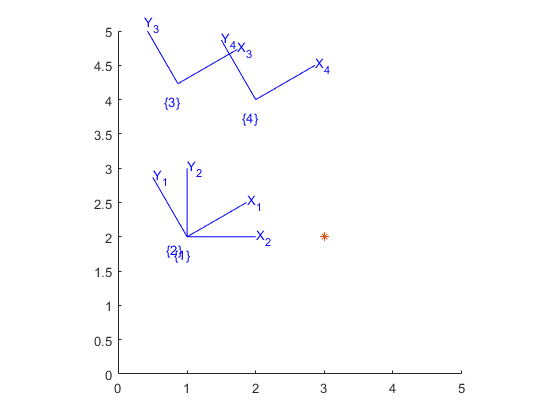

axis([0,5,0,5]); axis square; hold on
T1 = SE2(1,2,30,'deg');
T2 = SE2(1,2, 0,'deg');
T3 = T1 * T2;
T4 = T2 * T1;
% Plot T1 as a frame named 1 in blue
trplot2(T1, 'frame', '1', 'b')
% Plot T2 as a frame named 2 in red
trplot2(T2, 'frame', '2', 'r')
% Plot T3 as a frame named 3 in green
trplot2(T3, 'frame', '3', 'g')
% Plot T4 as a frame named 3 in green
trplot2(T4, 'frame', '4', 'c')
% Define a point in the world frame
P = [3,2]';
plot_point(P,'*');

% Compute the coordinates of P in frame 1
P1 = inv(T1.T) * [P; 1];